# Capstone Project - Combining Vision and Robotics RTDE

In this capstone exercise, you will combine computer vision and robot motion control to create a simple vision-based interaction with a Universal Robots UR3e manipulator. The goal is to detect selected fruits in a camera image, track their movement, and use this visual information to command Cartesian motion of the robot TCP.

The exercise connects several important robotics concepts into one practical workflow. First, you will use a YOLO object detector to identify fruits in the camera image and extract useful image features such as the object centroid and bounding box size. These features are then used to estimate how the fruit moves in the image and whether it moves closer to or farther away from the camera.

Based on the detected fruit type, two different control modes are implemented. In the first mode, the fruit motion is mapped to a Cartesian velocity command in the robot base frame, so that the TCP follows the perceived fruit movement. In the second mode, the fruit motion is interpreted in the TCP frame, so that the robot moves along its own tool axis, for example when the fruit moves toward or away from the camera.

The commanded Cartesian velocity is then converted into joint velocities using the robot Jacobian. To improve robustness near singular configurations, a damped least-squares pseudoinverse is used. Additional safety measures are included, such as Cartesian velocity saturation, joint velocity scaling, and dynamic workspace-based velocity scaling. The dynamic scaling reduces the robot velocity when the TCP approaches less desirable regions of the workspace and allows full speed only inside a preferred operating region.

By the end of this exercise, you should understand how image-based measurements can be transformed into robot motion commands, how Cartesian velocity control can be implemented using the Jacobian, and why safety mechanisms such as velocity limits, damping, and workspace-dependent scaling are necessary when controlling a real robot.

## Computer Vision

In the vision part of this exercise, you will use a camera and a YOLO object detector to identify selected fruits in the camera image. The detector returns bounding boxes, confidence scores, and class labels for the detected objects. From these detections, the exercise extracts the fruit with the highest confidence and computes two simple image features: the normalized centroid position and the normalized bounding box size.

These features are later used as input for the robot control loop. Changes in the centroid indicate how the fruit moves in the image plane, while changes in the bounding box size are used as a rough estimate of whether the fruit moves closer to or farther away from the camera. The output image is also annotated with the selected bounding box and centroid, so that the detection result can be visually checked during the experiment.

Setup the camera and Yolo Classifier 

cam = webcam(); 
det = yolov8ObjectDetector2('yolov8s');

### Fruit Detection Function

Setup the detection function below. 

The function should have the following inputs: 

- cam object

- yolo model

- required confidence 

- video quality scaling 

The fucntion should have the following outputs: 

- centroid

- Bounding box size (as hight and width)

- detected fruit with the highest confidence 

- output image with bounding box and centroid drawn into it

Behavior of the function, implement: 

- scaling of image quality using the function imresize()

- filter the detected categories, only return fruits

- only output fruits that have a confidence level above the threshold

- only output the fruit with the highest confidence level

- normalize the centroid position and bounding box size based on the image size (hight and width) 

function [centroid, BB_size, best_match_fruit, Iout] = Capstone_Fruit_Detection(cam, yolo_model, minConf, video_scale)
    best_match_fruit = "";
    Iout = [];
    
    % Get frame
    I = snapshot(cam);
    
    % Downsample
    I_small = imresize(I, video_scale);
    
    % Image/window size
    imageHeight = size(I_small, 1);
    imageWidth  = size(I_small, 2);
    
    % Run detector
    [bboxes, scores, labels] = detect(yolo_model, I_small);
    
    wantedFruits = ["banana", "apple", "orange"];
    
    % Keep only confident fruit detections
    idx = scores >= minConf & ismember(string(labels), wantedFruits);
    
    % Default outputs if nothing is found
    centroid = [];
    BB_size = [];
    bbox = [];
    score = [];
    
    if any(idx)
        % Filter detections
        filteredBboxes = bboxes(idx, :);
        filteredScores = scores(idx);
        filteredLabels = labels(idx);
    
        % Pick highest-confidence detection
        [score, bestIdx] = max(filteredScores);
    
        bbox = filteredBboxes(bestIdx, :);   % pixel bbox: [x y width height]
    
        best_match_fruit = string(filteredLabels(bestIdx));
    
        % Pixel centroid
        centroid_px = [bbox(1) + bbox(3)/2, ...
            bbox(2) + bbox(4)/2];
    
        % Pixel bounding box size
        BB_size_px = bbox(3:4);              % [width height]
    
        % Normalized centroid
        centroid = [centroid_px(1) / imageWidth, ...
            centroid_px(2) / imageHeight];
    
        % Normalized BB size relative to window/image size
        BB_size = [BB_size_px(1) / imageWidth, ...
            BB_size_px(2) / imageHeight];
    end
    

    Iout = I_small;

    if ~isempty(bbox)
        annotation = best_match_fruit + ": " + string(round(score, 2));

        Iout = insertObjectAnnotation(Iout, ...
            "rectangle", ...
            bbox, ...
            annotation);

        % For drawing, use pixel coordinates, not normalized coordinates
        centroid_px = [bbox(1) + bbox(3)/2, ...
            bbox(2) + bbox(4)/2];

        Iout = insertMarker(Iout, ...
            centroid_px, ...
            "x", ...
            "Size", 10);

        Iout = insertText(Iout, ...
            centroid_px + [8 8], ...
            "c = [" + string(round(centroid(1), 2)) + ", " + ...
            string(round(centroid(2), 2)) + "]", ...
            "FontSize", 12, ...
            "BoxOpacity", 0.6);
    end
end


create a figure to view the video feed

axis_handle = createCapstoneFigure(); 

you can show an image in this figure window by using the following syntax: 

imshow(Image, 'Parent', axis_handle); 

Test the classifier and tune the video scaling and confidence interval to accurate results at minimal computation time 

video_scale = 0.2; 
min_confidence = 0.6; 


[centroid, BB_size, best_match_fruit, Iout] = Capstone_Fruit_Detection(cam, det, min_confidence, video_scale);
% Display the output image with annotations
imshow(Iout, 'Parent', axis_handle)


## Robotics

In the robotics part of this exercise, the visual information from the fruit detector is converted into motion commands for the UR3e robot. The detected fruit movement is first mapped to a Cartesian velocity command, either in the robot base frame or in the TCP frame, depending on the selected control mode. This allows the robot to react differently to different fruit classes.

The Cartesian velocity command is then limited for safety and scaled based on the current TCP position inside the robot workspace. This dynamic workspace scaling reduces the commanded velocity near less desirable regions and allows full velocity only inside a preferred operating band. The final Cartesian velocity is converted into joint velocities using the robot Jacobian and a damped least-squares pseudoinverse, which improves robustness near singular configurations.

Before sending the command to the robot, the joint velocities are checked against predefined velocity limits and scaled if necessary. This ensures that the robot follows the visual command while respecting both Cartesian and joint-level safety constraints.

### Interprete fruit motion

receive the centroid position and bounding box dimensions from the detection function

compute the deltas as: 


$$\Delta \textrm{Centroid}\left(t\right)=\left\lbrack \begin{array}{c}
{\textrm{centroid}}_1 \left(t\right)-{\textrm{centroid}}_1 \left(t-1\right)\\
{\textrm{centroid}}_2 \left(t\right)-{\textrm{centroid}}_2 \left(t-1\right)
\end{array}\right\rbrack$$



$${\textrm{BB}}_{\textrm{area}} ={\textrm{BB}}_x \cdot {\textrm{BB}}_y$$



$$\Delta {\textrm{BB}}_{\textrm{area}} \left(t\right)={\textrm{BB}}_{\textrm{area}} \left(t\right)-{\textrm{BB}}_{\textrm{area}} \left(t-1\right)$$



$$\Delta {\textrm{BB}}_{\textrm{area}-\textrm{scaled}} =\frac{\Delta {\textrm{BB}}_{\textrm{area}} \left(t\right)}{{\textrm{BB}}_{\textrm{area}} \left(t-1\right)}$$


Two control mods should be implemented based on the tracked fruit. You need to map $\Delta \textrm{Centroid}\;$and $\Delta {\textrm{BB}}_{\textrm{area}-\textrm{scaled}}$ to the error vector. 

#### Base Fruit: 

map $\Delta \textrm{Centroid}\;$and $\Delta {\textrm{BB}}_{\textrm{area}-\textrm{scaled}}$ to the baseframe coordinates of your robot. The movement fruit movement should result in the same TCP movement. 

This could result in a error vector of: $e=\left\lbrack \begin{array}{c}
\Delta {\textrm{Centroid}}_1 \\
\Delta {\textrm{BB}}_{\textrm{area}-\textrm{scale}} \\
-\Delta {\textrm{Centroid}}_2 
\end{array}\right\rbrack$

#### TCP Fruit

when the TCP fruit it detected the TCP should move only along its Z-axis. Moving the fruit towards the camera should result in positive TCP Z movement. 

Map the fruit detection to single axis linear motion: 

- Choose the index with the largest absolute value and set the mapped error vector index to $\pm 1$

e.g. for a error vector of $e=\left\lbrack \begin{array}{c}
-0\ldotp 2\\
-0\ldotp 5\\
0\ldotp 4
\end{array}\right\rbrack$ the mapped error vector should be $e_{\textrm{mapped}} \left\lbrack \begin{array}{c}
0\\
-1\\
0
\end{array}\right\rbrack$

convert the error vector to velocities. 

you need to measure the amount of time between detections as dt, additionally you have to scale the raw_error with a velocity scaling as the resulting velocity could be too small or too large depending on your setup (computation time and camera image size)


$$v_{\textrm{cartesian}} =\frac{e_{\textrm{mapped}} }{\textrm{dt}}\cdot {\textrm{velocity}}_{\textrm{scaling}}$$


### Velocity Scaling

#### Basic Control gains: 

Scale the cartesian velocity with the gain matrix K matrix to obtain the control signal. 


$$v_{\textrm{input}} \;=K\cdot \;v_{\textrm{cartesian}}$$


#### Dynamic velocity scaling

Implement a **dynamic velocity scaling** based on the current TCP position inside the robot workspace. The goal is to reduce commanded Cartesian velocity when the TCP approaches regions that are considered unsafe or less desirable, and to allow full velocity only inside a preferred workspace band.

The scaling is based on the current TCP distance from the robot shoulder frame:

T_cur_reach = getTransform(ur, q, "tool0", "shoulder_link");

r_cur = norm(tform2trvec(T_cur_reach));

So the scalar value `r_cur` is the radial distance between the shoulder frame and the TCP. This distance is then used to compute a velocity scaling factor `s`, where:

s = 0

means the robot stops, and

s = 1

means the full commanded velocity is allowed. 

#### Derivation of the velocity regions

The workspace regions are derived from the robot’s home configuration. First, the TCP distance at the home pose is computed:

ur_home = [0,-pi/2,0,-pi/2,0,0]';
T_home = getTransform(ur, ur_home, "tool0", "shoulder_link");
R_home = norm(tform2trvec(T_home));

This value is used as the outer workspace limit:

r1 = R_home;

A preferred safe radius is defined as half of the home radius:

R_safe = 0.5 * R_home;

Around this safe radius, a velocity plateau is created. The width of this plateau transition region is:

band_width = 0.25 * R_home;

The two peak boundaries are then defined as:

r_peak1 = R_safe - band_width/2;
r_peak2 = R_safe + band_width/2;

The implemented radial regions are therefore:

r0      = 0;
r_peak1 = R_safe - band_width/2;
r_peak2 = R_safe + band_width/2;
r1      = R_home;

**Inner ramp-up region**

Between `r0` and `r_peak1`, the velocity is smoothly increased from zero to full speed:

x = (r_cur - r0) / (r_peak1 - r0);

s = 0.5 * (1 - cos(pi * x));

At `r_cur = r0`, this gives `s = 0`.

At `r_cur = r_peak1`, this gives `s = 1`.

**Outer ramp-down region**

Between `r_peak2` and `r1`, the velocity is gradually reduced from full speed to zero:

x = (r_cur - r_peak2) / (r1 - r_peak2);

s = 0.5 * (1 + cos(pi * x));

At `r_cur = r_peak2`, this gives `s = 1`.

At `r_cur = r1`, this gives `s = 0`.

**Scale the input velocity**

Finally scale the input velocity with the dynamic velocity scaling factor s


$$v_{\textrm{input}-\textrm{scaled}} =s\left(q\right)\cdot v_{\textrm{input}}$$


resulting in the following velocity profile

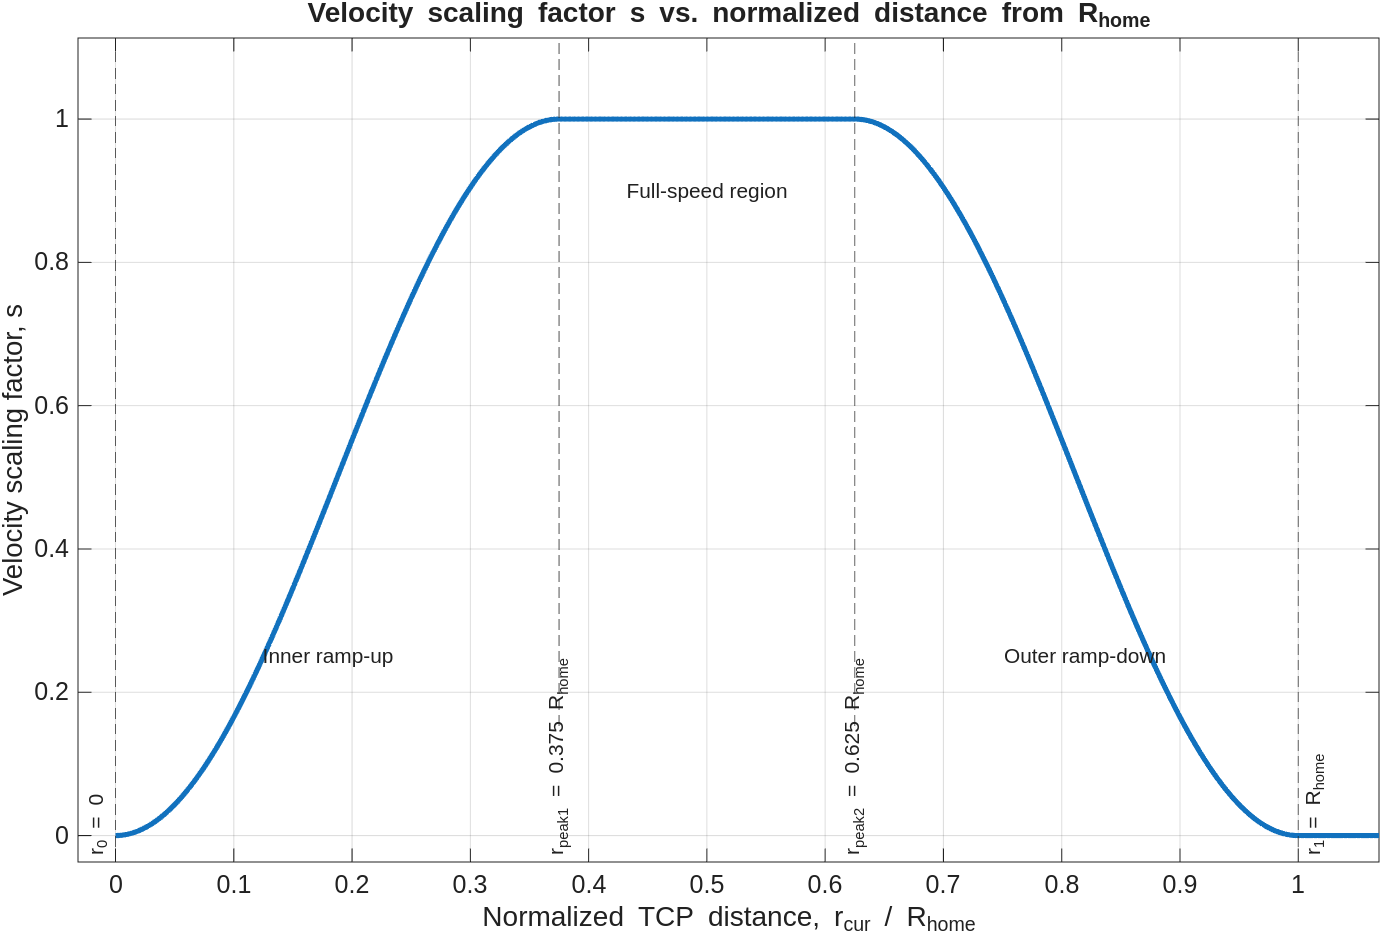

### Joint Velocity Computation

Use the following functions to get the robot state 

depending on the detected fruit you need to transform the TCP velocity into baseframe coordinates.


$$v_{\textrm{base}} \left\lbrace \begin{array}{ll}
v & \textrm{if}\;\textrm{detected}\;\textrm{fruit}=\textrm{Base}\;\textrm{fruit}\\
R\cdot v & \textrm{if}\;\textrm{detected}\;\textrm{fruit}=\textrm{TCP}\;\textrm{fruit}
\end{array}\right.$$


### Cartesian Velocity Saturation

Saturate the cartesian velocity by defining a maximum velocity of $v_{\textrm{linear}-\max } =0\ldotp 25\;\frac{m}{s}$ be aware of the velocity direction. 

### Damped Jacobian Pseudoinverse

compute the Jacobian, remember that the robotic system toolbox returns $J=\left\lbrack \begin{array}{c}
J_{\Theta \;} \\
J_p 
\end{array}\right\rbrack$

we now want to damp the jacobian based on its minimum singular value decomposition. you can obtain it using svd_min = min(svd(J))

- define a thereshhold when the damping starts svd_thresh = 0.2

- define a maximum damping factor e.g. lambda_max = 1

compute the damping factor lambda as follows: 


$$\lambda =\left\lbrace \begin{array}{ll}
\lambda =0 & \textrm{when}\;\sigma_{\min } \ge \sigma_{\textrm{thresh}} \\
\lambda =\lambda_{\max } \cdot \left(1-\min \left(1,{\textrm{sigma}}_{\min } \;/{\textrm{sigma}}_{\textrm{thresh}} \right)\right) & \textrm{when}\;\sigma_{\min } <\sigma_{\textrm{thresh}} 
\end{array}\right.$$


compute the damped pseudoinverse of the jacobian as: 


$$J_{\textrm{damped}}^{\dagger} =J^T \cdot {\left(J\cdot J^T +\lambda^2 \cdot I\right)}^{-1}$$


#### Compute Joint Velocities 

compute the joint velocities using the damped pseudoinverse jacobian as: 


$$\dot{\;q} =$$

$$J_{\textrm{damped}}^{\dagger} \cdot v_{\textrm{base}-\textrm{saturated}}$$


set the angular velocity part to 0. 

#### Scale/saturate the Joint Velocities 

Check if any of the previously defined joint velocity limits are violated, if so scale the entire $\dot{\;q}$ vector down so their relative velocities stay perserved. 

#### Apply joint velocities to the real robot

use the function sendSpeedJCommands(ur_rtde , q_dot) to send the joint velocities to the robot. 

## Control Loop

To obtain the current joint state use:

- q = readJointConfiguration(ur_rtde);

Dont query the detection at each timestep as the detection is compuationally expensive, instead implement a minimum time between image detections. 

For the overall loop use: 

- rate = rateControl(freq) 

- waitfor(rate) for the control loop 

Depending on your hardware you can display more things such as the manipulability elipsoid using 

- JointStatesToRviz(q, ur_model, [ ], 'Ellipsoid', true, 'EllipsoidResolution', 15);

- when using the RTDE implementation you have to send the joint states to Rviz to see the robot move. 

you can display the detection image in the previously created window using 

- imshow(Iout, 'Parent', axis_handle)

## Implementation

Move the robot in a non singular position to start use the freedrive mode on the teach pendant to reposition the TCP. 

setup the following constants here: 

- frequency and rate

- velocity scaling 

- Base fruit (string) 

- TCP fruit (string)

- sigma_thresh

- lambda_max

- v_linear_max

- minimum time between detections 

- load the ur model 

- define joint velocity limits

- gain matrix K

vel_scaling = 10*[1,1,1]';
Base_fruit = "orange"; 
TCP_fruit="apple"; 
freq = 80; 
rate = rateControl(freq);

sigma_thresh = 0.2; 
lambda_max = 1; 
v_linear_max = 0.25; 

min_time_between_detection = 0.3; 
ur = loadrobot("universalUR3e", DataFormat="column"); 
q_dot_limits = ones(6,1); 
K = diag([0.3,0.3,0.3]);

### Robotics Setup: 

Start The ROS applicatons to visualize the real robot

ur_model="universalUR3e"; 
StartTutorialApplication('Rviz', 'Model', ur_model); 
StartTutorialApplication('Trajectory', 'num_points',500); 
StartTutorialApplication('safety_nodes'); 

setup the UR RTDE object 

robot_ip="192.168.56.101"
ur_rtde=urRTDEClient(robot_ip); 

#### Visualize the Regions 

you can use the function VisualizeWorkspace(R_home) to display the workspace.

VisualizeWorkspace(R_home)

Initialize the variables and write the control loop below: 

% Initialize states
centroid_prev = [];
area_prev = [];
e_mapped = zeros(3,1);
detected_fruit = "";
last_detection_time = tic; 
v_input_saturated = zeros(3,1); 

while true
    if toc(last_detection_time)>min_time_between_detection
        [centroid, BB_size, detected_fruit, Iout] = Capstone_Fruit_Detection(cam, det, min_confidence, video_scale);
        imshow(Iout, 'Parent', axis_handle); 

        if ~isempty(centroid) && ~isempty(BB_size)
            area = BB_size(1) * BB_size(2);

            if isempty(centroid_prev) || isempty(area_prev)
                centroid_prev = centroid;
                area_prev = area;
                last_detection_time = tic;
                continue;
            end

            delta_centroid = centroid - centroid_prev;
            delta_area = area - area_prev;

            % Avoid division by zero
            if area > 0
                delta_area_scaled = delta_area / area;
            else
                delta_area_scaled = 0;
            end

            % Compute raw visual error / velocity signal
            if strcmp(Base_fruit, string(detected_fruit))

                % camera z axis is robot x, image left/right is y, image up/down is z
                e = [
                    
                    delta_centroid(1);
                    -1*delta_area_scaled;
                    -1*delta_centroid(2)
                ];

            elseif strcmp(TCP_fruit, string(detected_fruit))

                % camera z axis is tool z
                e = [
                    0;
                    0;
                    delta_area_scaled
                ];

            else
                e = zeros(3,1);
            end

            [~, idx_max] = max(abs(e));
            e_mapped = zeros(3,1); 
            e_mapped(idx_max)= 1;
            if e(idx_max)<0
                e_mapped=-e_mapped; 
            end
            if abs(e(idx_max))<0.05
                e_mapped=zeros(3,1); 
            end
            dt = toc(last_detection_time); 
            v_cartesian = e_mapped / dt .* vel_scaling;
            v_input = K * v_cartesian;
            v_input_saturated = min(max(v_input, -v_linear_max), v_linear_max);
            % Update memory
            centroid_prev = centroid;
            area_prev = area;

        else
            centroid_prev = [];
            area_prev = [];
            detected_fruit = "";
            v_input_saturated = zeros(3,1); 
        end

        last_detection_time=tic; 
    end
    try
            % --- Joint state ---
        q = readJointConfiguration(ur_rtde);

        % --- Tool pose in base ---
        T_base_tool = getTransform(ur, q, "tool0", "base_link");
        Rbt = T_base_tool(1:3,1:3);

        % --- Workspace radius in shoulder_link ---
        T_cur_reach = getTransform(ur, q, "tool0", "shoulder_link");
        r_cur = norm(tform2trvec(T_cur_reach));

        % --- Donut scaling ---
        if r_cur >= r1
            s = 0;
        elseif r_cur >= r_peak2
            x = (r_cur - r_peak2) / (r1 - r_peak2);
            s = 0.5 * (1 + cos(pi * x));
        elseif r_cur >= r_peak1
            s = 1;
        else
            if r_cur <= r0
                s = 0;
            else
                x = (r_cur - r0) / (r_peak1 - r0);
                s = 0.5 * (1 - cos(pi * x));
            end
        end
        v_scaled = s*v_input_saturated; 

        if detected_fruit == Base_fruit
            % e is interpreted directly in base frame
            v_lin_base = v_scaled;
        elseif detected_fruit == TCP_fruit
            % e is interpreted in TCP/tool frame and rotated into base frame
            v_lin_base = Rbt * v_scaled;
        else
            v_lin_base = zeros(3,1); 
        end

        % No rotational velocity
        v_ang_base = zeros(3,1);

        % Full Cartesian twist in [linear; angular] order
        v_cmd = [v_lin_base; v_ang_base];

        % --- Jacobian and DLS IK ---
        Jgeo = geometricJacobian(ur, q, "tool0");   % usually [omega; v]
        J = [Jgeo(4:6,:); Jgeo(1:3,:)];             % convert to [v; omega]

        sigma_min = min(svd(J));

        if sigma_min < sigma_thresh
            lambda = lambda_max * (1 - min(1, sigma_min / sigma_thresh));
        else
            lambda = 0;
        end
    

        pinvJ = J' / (J * J' + lambda^2 * eye(6));
        q_dot = pinvJ * v_cmd;

        % --- Joint velocity saturation ---
        ratio = abs(q_dot) ./ q_dot_limits;
        s_q = max(ratio);

        if s_q > 1
            q_dot = q_dot / s_q;
        end

       
        % --- Command + visualize ---
        sendSpeedJCommands(ur_rtde , q_dot);

        JointStatesToRviz(q, ur_model, [], ...
            "Ellipsoid", true, ...
            "EllipsoidResolution", 10);


        catch ME
        try
            sendSpeedJCommands(ur_rtde , zeros(6,1));
        catch
        end

        rethrow(ME);
    end
waitfor(rate);
end